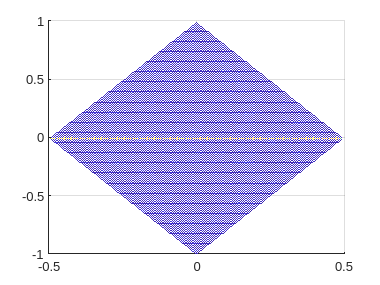

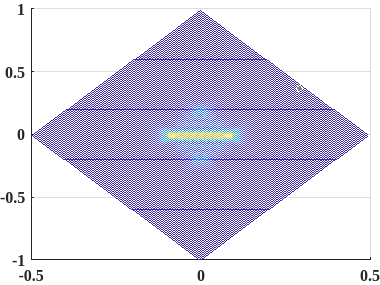

% Figure 1
N = 128;
M = 4;

fs = 128*1e6;
fc = 0e6;
B = 30e6;
T = 1e-6;
f_ordinate = zeros(N,N);
alfa_ordinate = zeros(N,N);
for i_1 = 1:N
    i_2 = 1:N;
    f_ordinate(i_1,i_2) = (i_1 + i_2 -1)/(2*N) - 1/2;
    alfa_ordinate(i_1,i_2) = (i_1 - i_2 + N - 1)/N - 1;
end
% 0. 随机信号
Num = 100; % 样本数
CS_RS = zeros(N,N);
parfor i = 1:Num
    signal_random = exp(1j*2*pi*rand(N,1));
    CS_RS = CS_RS + CF_diag(signal_random, N, M)/Num;
end
CS_RS = abs(CS_RS);
figure
mesh(f_ordinate, alfa_ordinate, CS_RS);view(0,90);
% 1. LFM
signal_LFM = generator_LFM(fs,fc,B,T);
CF_LFM = CF_diag(signal_LFM, N, M);
CF_LFM = abs(CF_LFM);
mesh(f_ordinate, alfa_ordinate, CF_LFM);
view(0,90);
xlabel('')
SetDrawStyle;